clear all; close all; clc

P = mod(11,2)

P = 1

Q = mod(2022+56, 4)

Q = 2

R = mod(11,4)

R = 3

S = mod(2022+56, 3)

S = 2

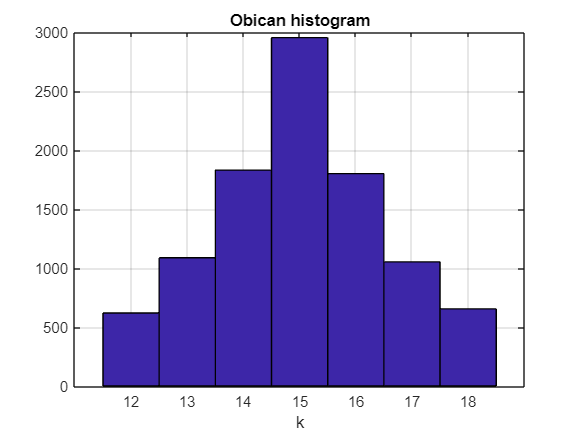


%%Histogram

N = 10000;
x = rand(1, N); 
k_values = 12:18; 
P_X = [0.29832936 * 0.6.^abs(k_values - 15)]; 
P_X = P_X / sum(P_X); 

verovatnoce = [P_X(1) P_X(2) P_X(3) P_X(4) P_X(5) P_X(6) P_X(7)];

p1 = P_X(1);
p2 = P_X(1) + P_X(2);
p3 = P_X(1) + P_X(2) + P_X(3);
p4 = P_X(1) + P_X(2) + P_X(3) + P_X(4);
p5 = P_X(1) + P_X(2) + P_X(3) + P_X(4) + P_X(5);
p6 = P_X(1) + P_X(2) + P_X(3) + P_X(4) + P_X(5) + P_X(6);
p7 = 1; 

X = zeros(1, N);

for i = 1:N
    if x(i) < p1
        X(i) = 12;
    elseif x(i) < p2
        X(i) = 13;
    elseif x(i) < p3
        X(i) = 14;
    elseif x(i) < p4
        X(i) = 15;
    elseif x(i) < p5
        X(i) = 16;
    elseif x(i) < p6
        X(i) = 17;
    else
        X(i) = 18;
    end
end

figure;
hist(X, k_values); 
title('Obican histogram');
xlabel('k');
grid on;

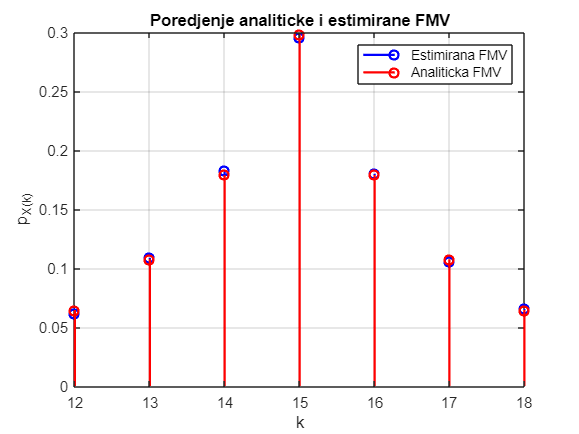


p_exp = zeros(size(k_values)); 
for j = 1:length(k_values)
    p_exp(j) = sum(X == k_values(j)) / N; 
end

F_exp = zeros(size(k_values)); 
for j = 1:length(k_values)
    F_exp(j) = sum(p_exp(1:j)); 
end

F_theo = cumsum(P_X); 

figure;
stem(k_values, p_exp, 'b', 'LineWidth', 1.5, 'DisplayName', 'Estimirana FMV', 'Marker', 'o');
hold on;
stem(k_values, P_X, 'r', 'LineWidth', 1.5, 'DisplayName', 'Analiticka FMV', 'Marker', 'o');
title('Poredjenje analiticke i estimirane FMV');
xlabel('k');
ylabel('p_X(k)');
legend('show');
grid on;

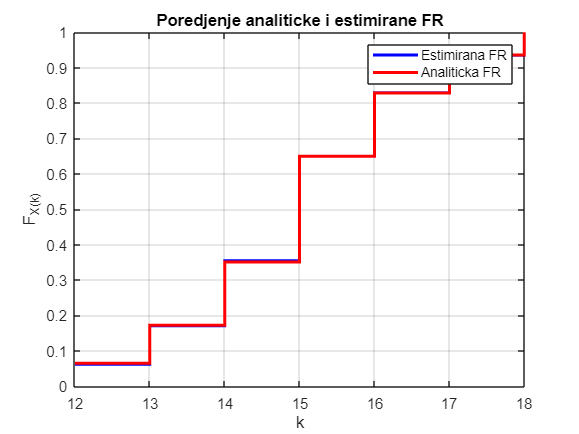


figure;
stairs(k_values, F_exp, 'b', 'LineWidth', 2, 'DisplayName', 'Estimirana FR');
hold on;
stairs(k_values, F_theo, 'r', 'LineWidth', 2, 'DisplayName', 'Analiticka FR');
title('Poredjenje analiticke i estimirane FR');
xlabel('k');
ylabel('F_X(k)');
legend('show');
grid on;


m = sum(X)/N

m = 15.0156

var = sum((X-m).^2)/(N-1)

var = 2.3488